# 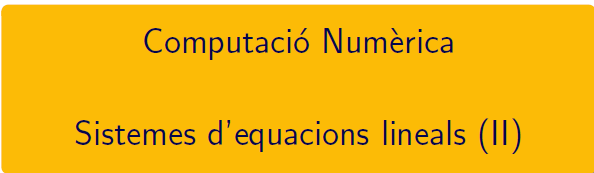

==========================================================================

# TEMA 2. Sistemes lineals sobredeterminats

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-CNLab4-5.pdf i en el document CN_full3.pdf, els podeu trobar en el campus virtual. 

## Sistemes sobredeterminats

Un sistema **Ax=b**, on A és una matriu mxn (m>n) i de rang n es diu sistema sobredeterminat.  No existeix $x=(x_1,x_2,\cdots,x_n)^t$ solució. 


$$S = \left\{ \begin{array}{rcrcrcrcr}
x & + & y & + & z &   &    & = & 2\\ 
x &   &   & + & z & + & 2t & = & 3\\ 
x & + & y &   &   & + & t  & = & 4\\
& - & y & + & 2z&   &    & = & 2\\ 
-x & + & y & - & z & + & t  & = & 1
\end{array}\right.$$


`Exercici 1`` Escriviu A i b i calculeu rang(A), per al sistema d'equacions S`

A = [1 1 1 0; 1 0 1 2; 1 1 0 1; 0 -1 2 0; -1 1 -1 1];
b = [2; 3; 4; 2; 1];
rA = rank(A), rA == rank([A,b]) % Sistema d'equacions incompatible

rA = 4

ans = logical
   0


### Solució per mínims quadrats

Trobar $x=(x_1,x_2,\cdots,x_n)^t$ tal que el vector residu ${\bf r} =\| r(x)\|_2 =  \|b-Ax\|_2 $ sigui el més petit posible, valor mínim.

- Geomètricament, ${\bf Ax} = x_1\left( \begin{array}{l}a_{11}\\\vdots\\a_{m1}\end{array}\right)+\cdots+x_1\left( \begin{array}{l}a_{1n}\\\vdots\\a_{mn}\end{array}\right)$ es tracta de trobar la combinació lineal dels vectors columna de la matriu $\bf A$més propera al vector $\bf b$. La distància és $r(x) = b-Ax$, i el mínim es dona quan el vector $r(x)$ és perpendicular al subespai generat per els vectors columna de la matriu $\bf A$. Les equacions són ${\bf A^t\,r=A^t(b-Ax)=0}$. 

- Analíticament, si $x=(x_1,x_2,\cdots,x_n)^t$, $ {\bf r}^2\, =\displaystyle \sum_{i=1}^{m}(a_{i1}x_1+\cdots+a_{in}x_n-b_i)^2 = \displaystyle \sum_{i=1}^{m}\left( \sum_{j=1}^{n}a_{ij}x_j-b_i\right)^2$.  Els extrems locals han de verificar $\frac{\partial\, {\bf r^2}}{\partial x_j} =0$  per a tot $j=1,\dots,m$. Aquesta condició és  $2\displaystyle \sum_{i=1}^{m}\left( \sum_{k=1}^{n}a_{ik}x_k-b_i\right)^2 a_{ij} = 0$ ,  o $\displaystyle \sum_{i=1}^{m}\sum_{j=1}^{n}a_{ij}a_{ik}x_k = \sum_{i=1}^{m}a_{ij}b_i$ per a tot $j=1,\dots,m$. Escrit més compacte ${\bf A^tb=A^tAx}$.  

`Exercici 2`` Calcula `$A^tA$`, rang(`$A^tA$`) , det(`$A^tA$`)  i comproba que el sistema `${A^tAx=A^tb}$` és compatible determinat. (sistema d'equacions S)`

B = A'*A

B =      4     1     3     2
     1     4    -2     2
     3    -2     7     1
     2     2     1     6


rB = rank(B)

rB = 4

d = det(B)

d = 175

rBM = rank([B,A'*b])

rBM = 4

compatible = (rB == rBM)  % Sistema d'equacions compatible determinat

compatible = logical
   1


`Exercici 3`` Calcula `$x=(x_1,x_2,\cdots,x_n)^t$`  solució del sistema `${A^tAx=A^tb}$`.  (sistema d'equacions S)`

x = linsolve(B, A'*b), X = lsqminnorm(A,b)

x =     0.1429
    1.2857
    1.2857
    1.1429


X =     0.1429
    1.2857
    1.2857
    1.1429


`Exercici 4`` Calculeu el vector residu en la solució. Comproveu que `$y=(0,-1,2,-1)^t$`  té residu més gran, es a dir la solució compleix la propietat de `$\min_{x}(\, {\bf r}^2\, )$`. (sistema d'equacions S)`

rx = norm(b-A*x,2)

rx = 1.8898

ry = norm(b-A*[0;-1;2;-1],2)

ry = 8.9443

y = rand(size(x)); ry2 = norm(b-A*y,2), minim_cert_fals = (rx < ry2)

ry2 = 3.6561

minim_cert_fals = logical
   1


### Pràctica 3. Equacions normals

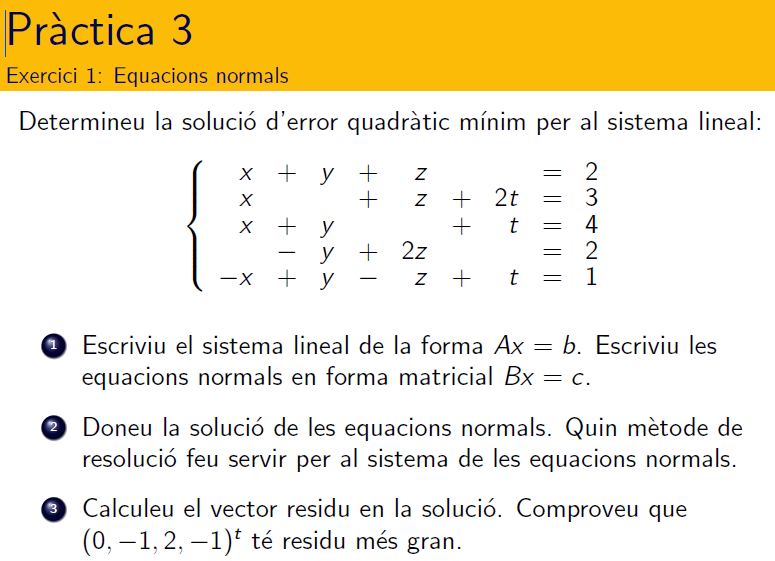

`Exercici 1`` Escriviu A i b i calculeu rang(A), enunciat associat a la pràctica 3`

A = [1 1 1 0; 1 0 1 2; 1 1 0 1; 0 -1 2 0; -1 1 -1 1];
b = [2; 3; 4; 2; 1];

`Exercici 2`` Calcula `$A^tA$`, rang(`$A^tA$`) , det(`$A^tA$`)  i comproba que el sistema `${A^tAx=A^tb}$` és compatible determinat.`

B = A'*A

B =      4     1     3     2
     1     4    -2     2
     3    -2     7     1
     2     2     1     6


rB = rank(B)

rB = 4

d = det(B)

d = 175

rBM = rank([B,A'*b])

rBM = 4

compatible = (rB == rBM)  % Sistema d'equacions compatible determinat

compatible = logical
   1


`Exercici 3`` Calcula `$x=(x_1,x_2,\cdots,x_n)^t$`  solució del sistema `${A^tAx=A^tb}$`. `

x = linsolve(B, A'*b), X = lsqminnorm(A,b)

x =     0.1429
    1.2857
    1.2857
    1.1429


X =     0.1429
    1.2857
    1.2857
    1.1429


`Exercici 4`` Calculeu el vector residu en la solució. Comproveu que `$y=(0,-1,2,-1)^t$`  té residu més gran, es a dir la solució compleix la propietat de `$\min_{x}(\, {\bf r}^2\, )$`. `

rx = norm(b-A*x,2)

rx = 1.8898

ry = norm(b-A*[0;-1;2;-1],2)

ry = 8.9443

y = rand(size(x)); ry2 = norm(b-A*y,2), minim_cert_fals = (rx < ry2)

ry2 = 2.9984

minim_cert_fals = logical
   1


### Pràctica 4. Ajust per paràbola

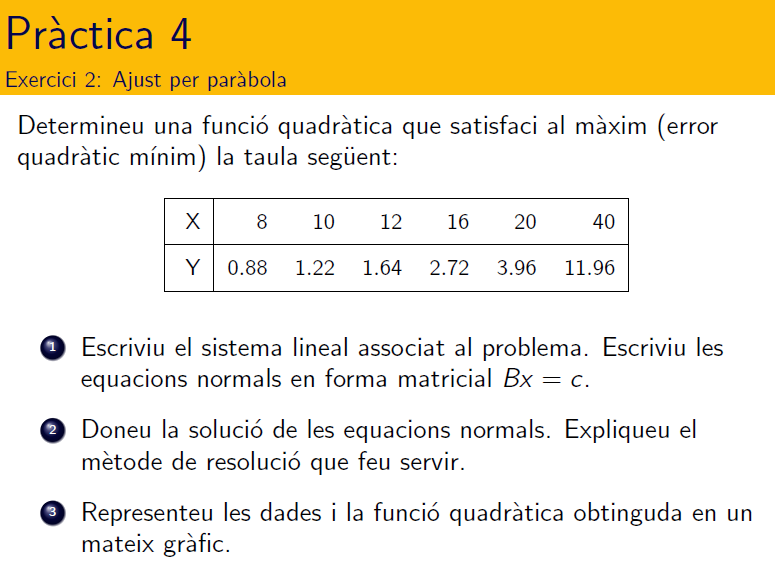

`Exercici 1`` Escriviu el sistema lineal associat al problema,  Ax=b, explícita A, b i rang(A).`

X = [8 10 12 16 20 40]';
A = [X.^2, X, ones(size(X))]

A =           64           8           1
         100          10           1
         144          12           1
         256          16           1
         400          20           1
        1600          40           1


b = [0.88 1.22 1.64 2.72 3.96 11.96]', Y = b;

b =     0.8800
    1.2200
    1.6400
    2.7200
    3.9600
   11.9600


rA = rank(A)

rA = 3

`Exercici 2`` Calcula `$A^tA$`, rang(`$A^tA$`) , det(`$A^tA$`)  i comproba que el sistema `${A^tAx=A^tb}$` és compatible determinat.`

B = A'*A

B =      2820368       79336        2564
       79336        2564         106
        2564         106           6


rB = rank(B)

rB = 3

d = det(B)

d = 2.0221e+08

rBM = rank([B,A'*b])

rBM = 3

compatible = (rB == rBM)

compatible = logical
   1


`Exercici 3`` Calcula `$x=(x_1,x_2,\cdots,x_n)^t$`  solució del sistema `${A^tAx=A^tb}$`. `

x = linsolve(B, A'*b), x = lsqminnorm(A,b)

x =     0.0045
    0.1307
   -0.5166


x =     0.0045
    0.1307
   -0.5166


`Exercici 4`` Representeu les dades i la funció quadràtica obtinguda en un mateix gràfic. `

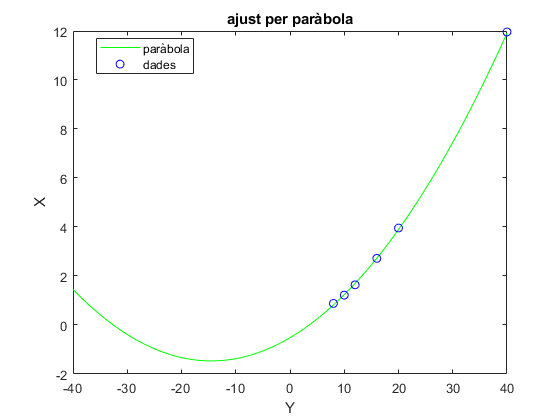

x = linspace(-40,40);
plot(x, 0.0045*x.^2+0.1307*x-0.5166,'g')
hold on
plot(X,Y,'bo')
hold off
title('ajust per paràbola');
xlabel('Y'); ylabel('X');
legend('paràbola','dades','Location','best')

### Pràctica 5. Sistema d'equacions sobredeterminat

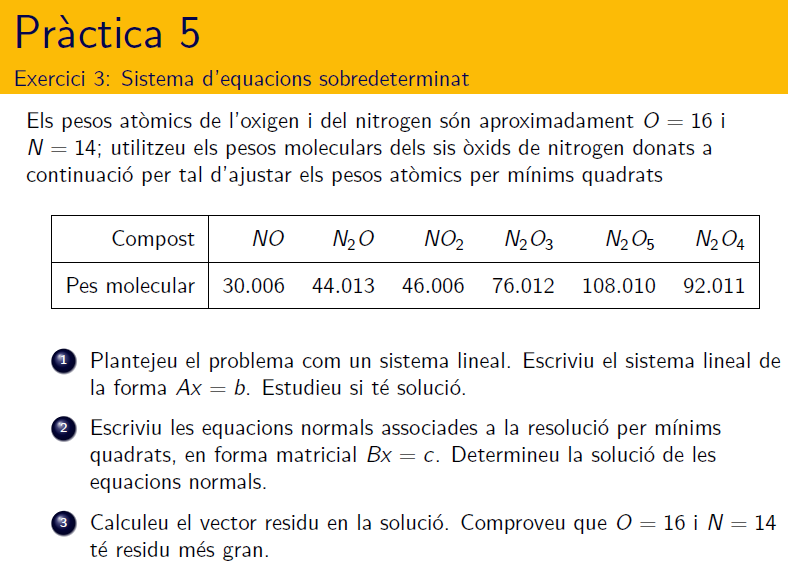

`Exercici 1`` Escriviu A i b i calculeu rang(A), enunciat associat a la pràctica 5`

A = [[1 2 1 2 2 2]',[1 1 2 3 5 4]']

A =      1     1
     2     1
     1     2
     2     3
     2     5
     2     4


b = [30.006 44.013 46.006 76.012 108.010 92.011]'

b =    30.0060
   44.0130
   46.0060
   76.0120
  108.0100
   92.0110


rank(A)

ans = 2

`Exercici 2`` Calcula `$A^tA$`, rang(`$A^tA$`) , det(`$A^tA$`)  i comproba que el sistema `${A^tAx=A^tb}$` és compatible determinat.`

B = A'*A

B =     18    29
    29    56


rB = rank(B)

rB = 2

d = det(B)

d = 167.0000

rBM = rank([B,A'*b])

rBM = 2

compatible = (rB == rBM)

compatible = logical
   1


`Exercici 3`` Calcula `$x=(x_1,x_2,\cdots,x_n)^t$`  solució del sistema `${A^tAx=A^tb}$`. `

x = linsolve(B, A'*b)

x =    14.0069
   15.9993


`Exercici 4``  Calculeu el vector residu en la solució. Comproveu que `$O=16$` i `$N=14$` té residu més gran, es a dir la solució compleix la propietat de `$\min_{x}(\, {\bf r}^2\, )$`. `

rx = norm(b-A*x,2)

rx = 6.9213e-04

ry = norm(b-A*[14;16],2)

ry = 0.0246

minim_cert_fals = (rx < ry)

minim_cert_fals = logical
   1


### Pràctica 6. Corba amb millor ajust

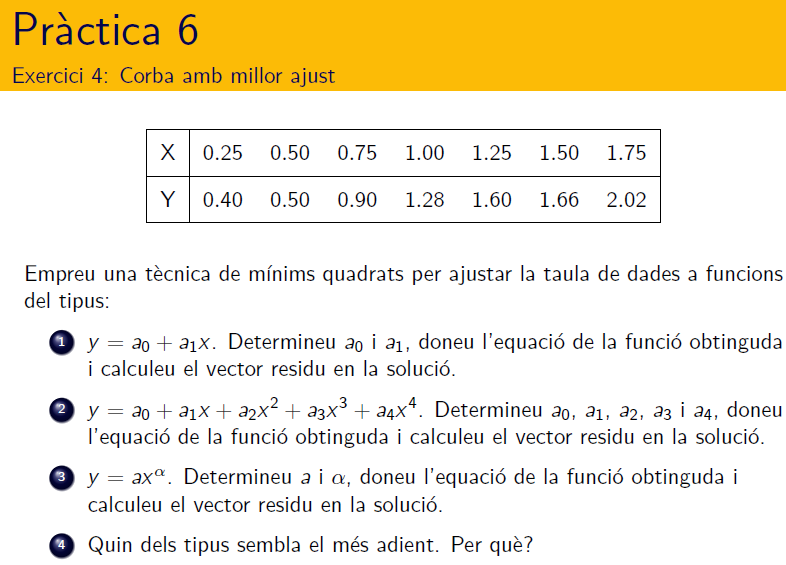

`Exercici 1`` Escriviu el sistema lineal associat al problema de representar les dades per una ``recta``,  Ax=b, explícita A, b i rang(A). Calcula `$x=(x_1,x_2,\cdots,x_n)^t$`  solució del sistema `${A^tAx=A^tb}$`. Calculeu el vector residu en la solució.`

A = [0.25 0.50 0.75 1.00 1.25 1.50 1.75];
A = [A', ones(size(A))']

A =     0.2500    1.0000
    0.5000    1.0000
    0.7500    1.0000
    1.0000    1.0000
    1.2500    1.0000
    1.5000    1.0000
    1.7500    1.0000


b = [0.40 0.50 0.90 1.28 1.60 1.66 2.02]'

b =     0.4000
    0.5000
    0.9000
    1.2800
    1.6000
    1.6600
    2.0200


rA = rank(A)

rA = 2

coef_recta = linsolve(A, b)

coef_recta =     1.1257
    0.0686


r_recta = norm(b-A*coef_recta,2)

r_recta = 0.2292

`Exercici 2`` Escriviu el sistema lineal associat al problema de representar les dades per una ``polinomi de grau 4``,  Ax=b, explícita A, b i rang(A). Calcula `$x=(x_1,x_2,\cdots,x_n)^t$`  solució del sistema `${A^tAx=A^tb}$`. Calculeu el vector residu en la solució.`

X = [0.25 0.50 0.75 1.00 1.25 1.50 1.75];
A = [X.^4',X.^3',X.^2', A]

A =     0.0039    0.0156    0.0625    0.2500    1.0000
    0.0625    0.1250    0.2500    0.5000    1.0000
    0.3164    0.4219    0.5625    0.7500    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000
    2.4414    1.9531    1.5625    1.2500    1.0000
    5.0625    3.3750    2.2500    1.5000    1.0000
    9.3789    5.3594    3.0625    1.7500    1.0000


b = [0.40 0.50 0.90 1.28 1.60 1.66 2.02]'

b =     0.4000
    0.5000
    0.9000
    1.2800
    1.6000
    1.6600
    2.0200


rA = rank(A)

rA = 5

coef_polinomi = linsolve(A, b)

coef_polinomi =     2.2497
   -9.4255
   13.3333
   -6.0767
    1.2286


r_polinomi = norm(b-A*coef_polinomi,2)

r_polinomi = 0.0689

`Exercici 3`` Escriviu el sistema lineal associat al problema de representar les dades per una ``corba potencial``,  Ax=b, explícita A, b i rang(A). Calcula `$x=(x_1,x_2,\cdots,x_n)^t$`  solució del sistema `${A^tAx=A^tb}$`. Calculeu el vector residu en la solució.`

X = [0.25 0.50 0.75 1.00 1.25 1.50 1.75];
A = [log(X)', ones(size(X))']

A =    -1.3863    1.0000
   -0.6931    1.0000
   -0.2877    1.0000
         0    1.0000
    0.2231    1.0000
    0.4055    1.0000
    0.5596    1.0000


b = log([0.40 0.50 0.90 1.28 1.60 1.66 2.02])'

b =    -0.9163
   -0.6931
   -0.1054
    0.2469
    0.4700
    0.5068
    0.7031


rA = rank(A)

rA = 2

coef_corba = linsolve(A, b)

coef_corba =     0.8958
    0.1811


r_corba = norm(b-A*coef_corba,2)

r_corba = 0.3161

a = 1.1986      % averiguar perqué

a = 1.1986

`Exercici 4`` Representeu les dades, la recta, el polinomi de grau 4 i la corba potencial en un mateix gràfic.`

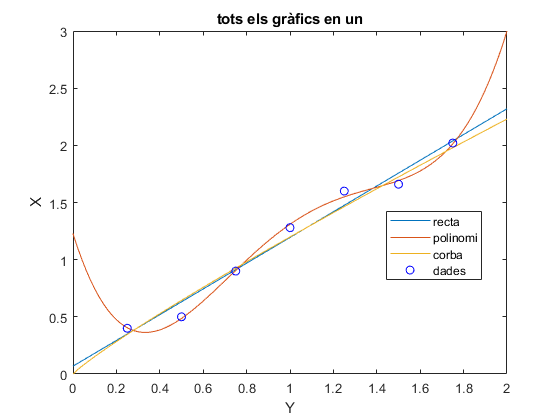

X = [0.25 0.50 0.75 1.00 1.25 1.50 1.75];
Y = [0.40 0.50 0.90 1.28 1.60 1.66 2.02];
t = linspace(0,2);
fr = @(x) 1.1257*x + 0.0686; 
fp = @(x) 2.2497*x.^4 - 9.4255*x.^3 + 13.3333*x.^2 - 6.0767*x + 1.2286;
fc = @(x) 1.1986*x.^0.8958;
plot(t,fr(t),t,fp(t),t,fc(t))
hold on
plot(X,Y,'bo')
hold off
title('tots els gràfics en un');
xlabel('Y'); ylabel('X');
legend('recta','polinomi','corba','dades','Location','best')

`Exercici 5`` Quin tipus sembla més adient? Raona i argumenta la teva resposta. `

r_recta, r_polinomi, r_corba

r_recta = 0.2292

r_polinomi = 0.0689

r_corba = 0.3161

`Document preparat per M. Àngela Grau Gotés, 9 de març de 2021`